clear;
file = 'potdng';

%ims = zeros(4, 2000-16, 1500-16, 3, 'single');
ims = zeros(4, 2000-24, 1500-24, 3, 'single');

for x=0:1:3
    deg = num2str(45 * x);
    ims(x+1, :, :, :) = imread(strcat('cut/', file, deg, '.tif'));
end
clear x;
clear deg;

ims = rgb2lin(ims / 255.0);
imsfft = fft(ims, 4, 1) * 0.5;
clear ims;

imsfftmean = squeeze(imsfft(1, :, :, :)) * 0.5; % 0.5 * Diffuse + 0.5 * Perp + 0.5 * Parallel
imsfftcosine = squeeze(abs(imsfft(2, :, :, :))); % 0.5 * (Perp - Parallel)
clear imsfft;

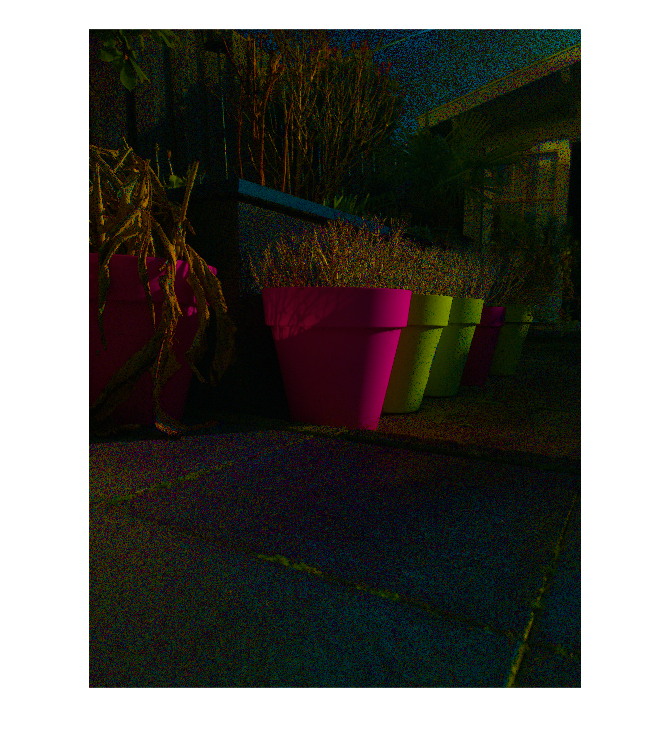

% Select channel with lowest coefficient for projection on boundary.
CosFactor = min(imsfftmean ./ max(0.001, imsfftcosine), [], 3);
imshow(lin2rgb(imsfftmean - (CosFactor .* imsfftcosine)));


% Convert to GPU.
MeanRGB = gpuArray(imsfftmean);
CosRGB = gpuArray(imsfftcosine);
CosFactor = gpuArray(CosFactor);

[qytotal, qxtotal] = size(CosFactor);
qypart = qytotal / 4;
qxpart = qxtotal / 4;

IterCount = 3;
for i = 1:IterCount
    % Left.
    %ProjOntoCosineIter(1:end, 1:(end-1)) = min(ProjOntoCosineIter(1:end, 1:(end-1)), ProjOntoCosineIter(1:end, 2:end));
    % Right.
    %ProjOntoCosineIter(1:end, 2:end) = min(ProjOntoCosineIter(1:end, 1:(end-1)), ProjOntoCosineIter(1:end, 2:end));
    % Up.
    %ProjOntoCosineIter(1:(end-1), 1:end) = min(ProjOntoCosineIter(1:(end-1), 1:end), ProjOntoCosineIter(2:end, 1:end));
    % Down.
    %ProjOntoCosineIter(2:end, 1:end) = min(ProjOntoCosineIter(1:(end-1), 1:end), ProjOntoCosineIter(2:end, 1:end));
    
    % Do the bilateral update based on Fresnel ratios at once.
    CosFactor = bilateralx(CosFactor, MeanRGB, 3.0, 0.05, @(x) ((x + 0.05) .^ -3.0));

    % Divide line-intersection in 16 sub-parts for memory usage.
    for qy = 0:0
        yoffset = qypart * qy;
        ycoords = (yoffset+1):(yoffset+qypart);
        for qx = 0:0
            xoffset = qxpart * qx;
            xcoords = (xoffset+1):(xoffset+qxpart);
            tic;
            CosFactor(ycoords, xcoords) = bilaterallinex(ycoords, xcoords, MeanRGB, CosRGB, CosFactor);
            toc;
        end
    end
end

Elapsed time is 10.759841 seconds.
Elapsed time is 11.174542 seconds.
Elapsed time is 11.018123 seconds.


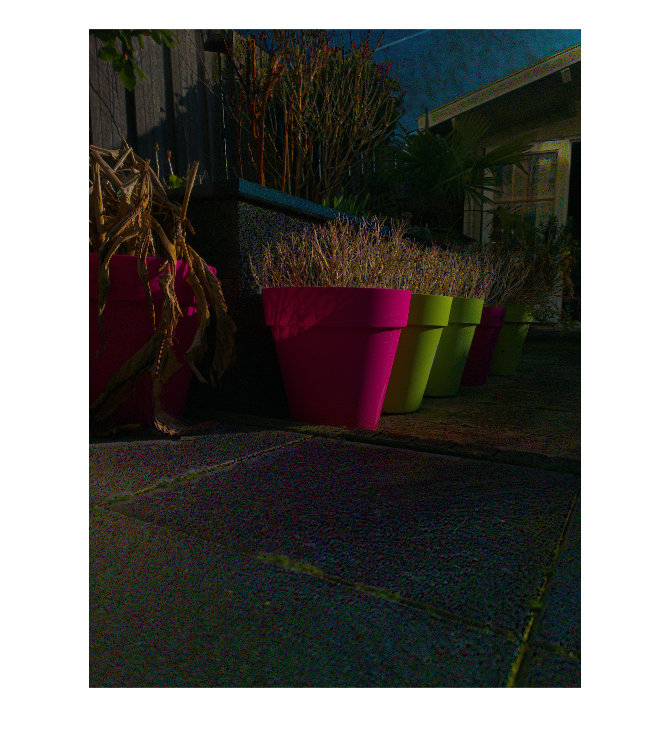


% Convert to CPU.
CosFactor = gather(CosFactor);

imshow(lin2rgb(imsfftmean - (CosFactor .* imsfftcosine)));

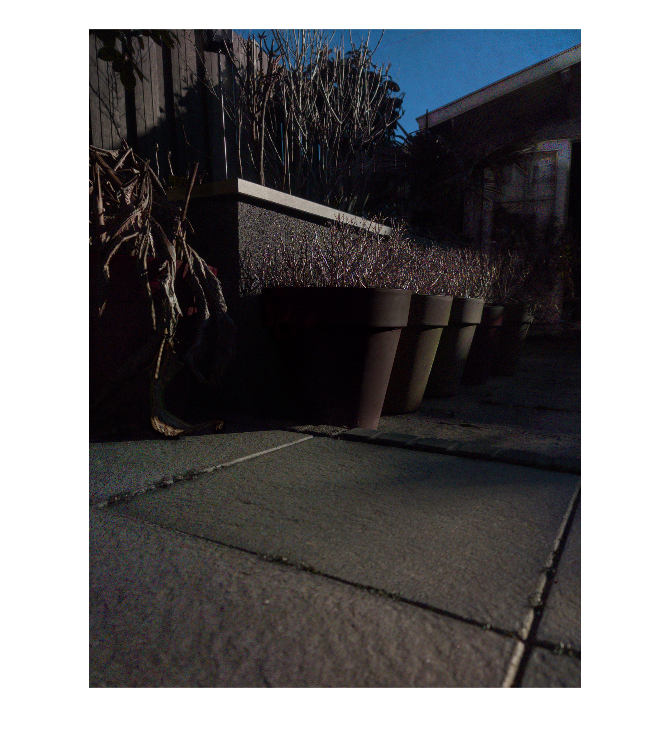

%imshow(lin2rgb(imsfftmean));
imshow(lin2rgb(CosFactor .* imsfftcosine));

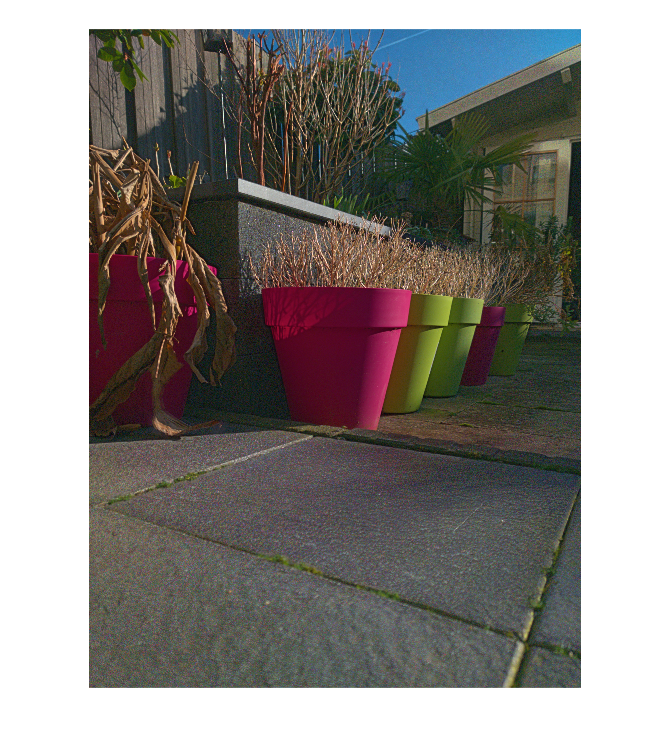

Specular = CosFactor .* gpuArray(imsfftcosine);
Diffuse = gpuArray(imsfftmean - Specular);

imggpu = max(0, Diffuse);
imgbil = bilateral(imggpu, 4.0, 0.15);

imghsv = rgb2hsv(imggpu);
imgbilhsv = rgb2hsv(imgbil);

imghsvbase = imgbilhsv(:, :, 3);
imghsvdetail = imghsv(:, :, 3) ./ imghsvbase;

imghsvcombine = imghsv;
imghsvcombine(:, :, 3) = tonemap(imghsvbase, imghsvdetail, 0.65, 1.35);

imshow(lin2rgb(gather(hsv2rgb(imghsvcombine) + Specular)));